# Exercise #2: Controller Design & Tuning

In this exercise, you will design a controller using the Control System Tuner app that will follow a given spacecraft attitude profile. 

## Part 1: PD Control

In this part you will

- Initialize the spacecraft parameters

- Open the model with PD controllers

- Familiarize yourself with the Control System Tuner App

- Set up the tuning rules and conditions and tune the controllers

- Observe the results

- Tune the controllers by hand and compare

### 1) Initialize the spacecraft parameters

**Run this section** to initialize the spacecraft parameters.

% Inertia matrix
I = [1 0 0;
     0 2 0;
     0 0 3];

% Initial attitude (deg)
initThetaX = 0;
initThetaY = 0;
initThetaZ = 0;

% Initial angular velocity (deg/s)
initOmegaX = 0;
initOmegaY = 0;
initOmegaZ = 0;

### 2) Open the model with PD controllers

**Run this section **to open the model.

open_system Exercise2_untunedPID

### 3) Familiarize yourself with the Control System Tuner App

In the Simulink window, **open the Control System Tuner App from the Apps tab**.

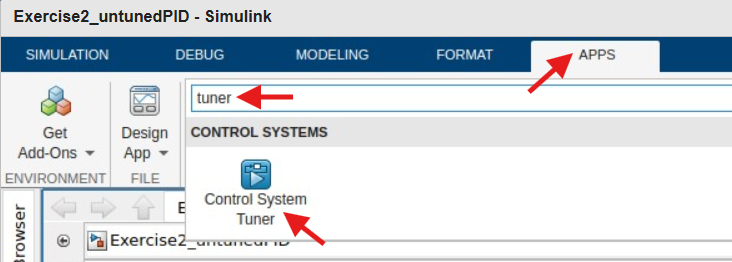

### 4) Set up the tuning rules and conditions and tune the controllers

**Do it yourself!** Follow the tuning steps in the [Exercise 2 Supplemental](matlab: open Exercise2Supplement) live script.

or

**Open a session that is ready to go! **In the Control System Tuner App, open the session "Exercise2_UntunedPIDSession.mat". 

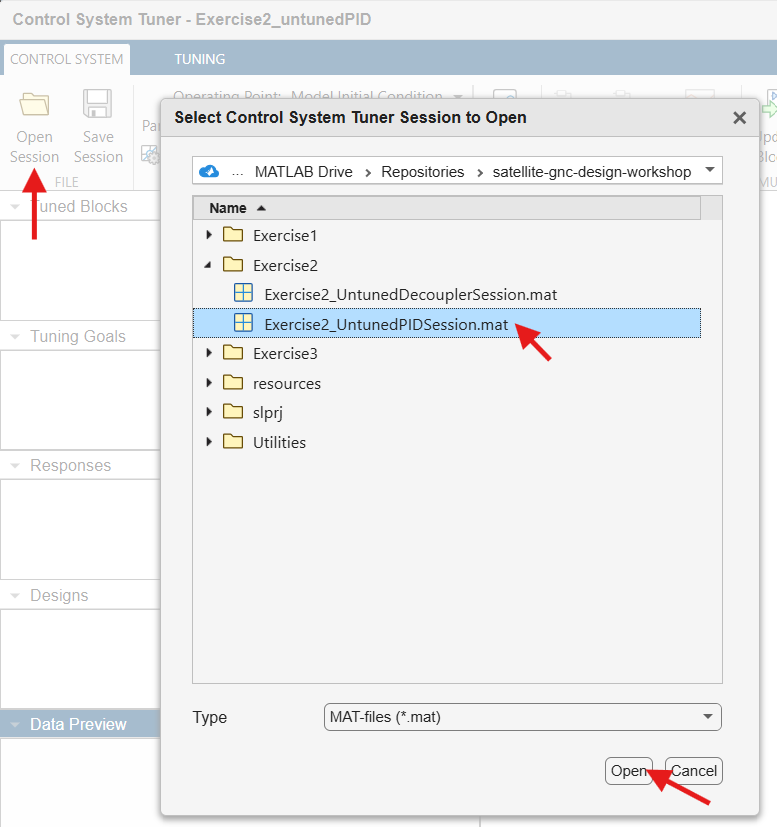

Notice how our current untuned gains don't meet our reference tracking goal - the tracking error exceeds the maximum allotted and is in the yellow-colored region of the plot. **On the Tuning tab, click "Tune"** to have Control System Tuner find gain values that meet our criteria.

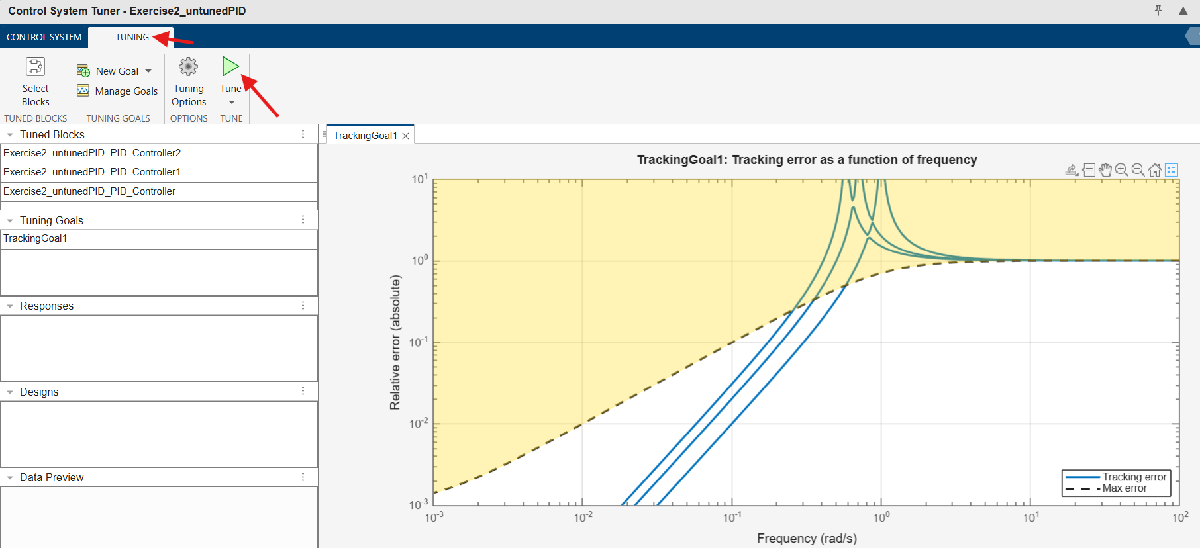

After tuning, the tracking error should not be in the yellow-colored region of the plot. **Click "Tune" a couple more times **to see how the solution improves with multiple tunes.

Once you have results you're happy with, you can update the PID blocks with the new gain values by **navigating to the Control System tab and clicking "Update Blocks"**. 

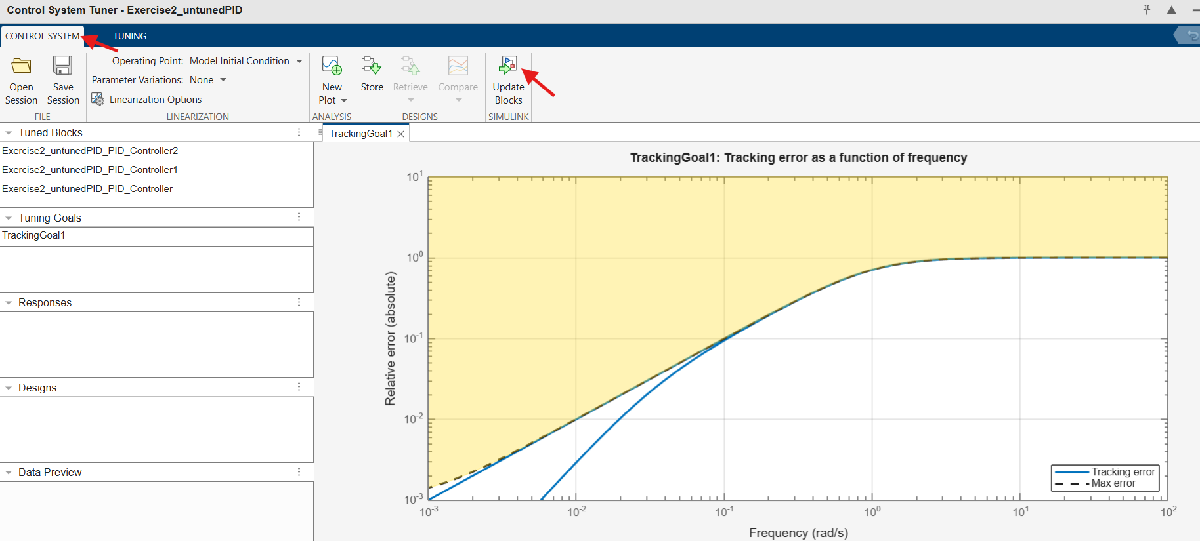

#### 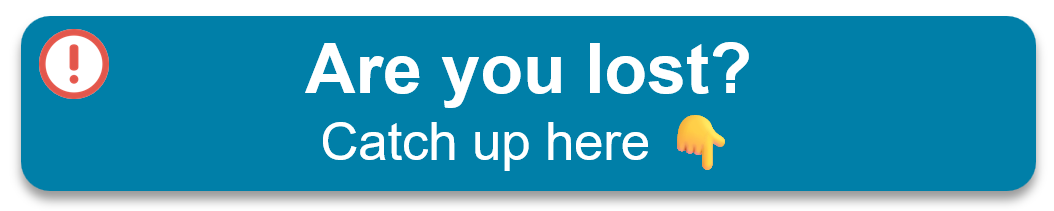

Catch up by [opening the solution model](matlab:open_system Exercise2_tunedPID) to evaluate the performance with these tuned gain values.

### 5) Observe the results

In the Simulink window, **run the tuned model.**

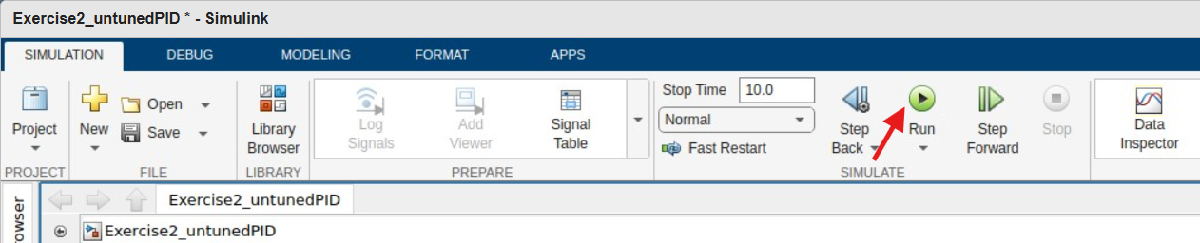

**Open the Data Inspector **to view controller performance from the simulation run.

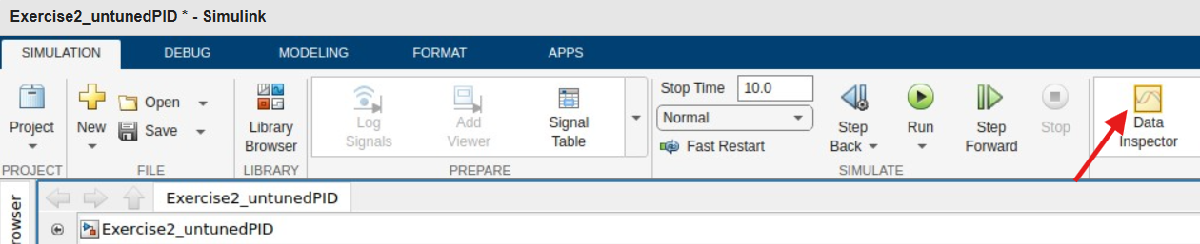

**Adjust the number and arrangement of the displays **in the Data Inspector so phi, theta, and psi can each have their own plot.

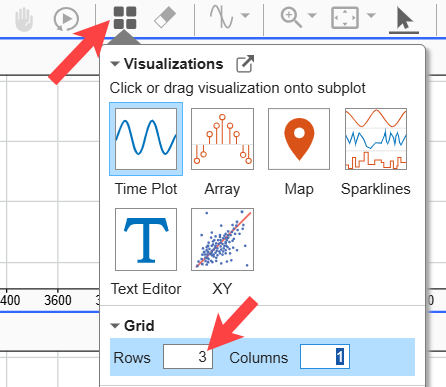

**Plot the reference signal (r_) and output (y_) for each axis.**        

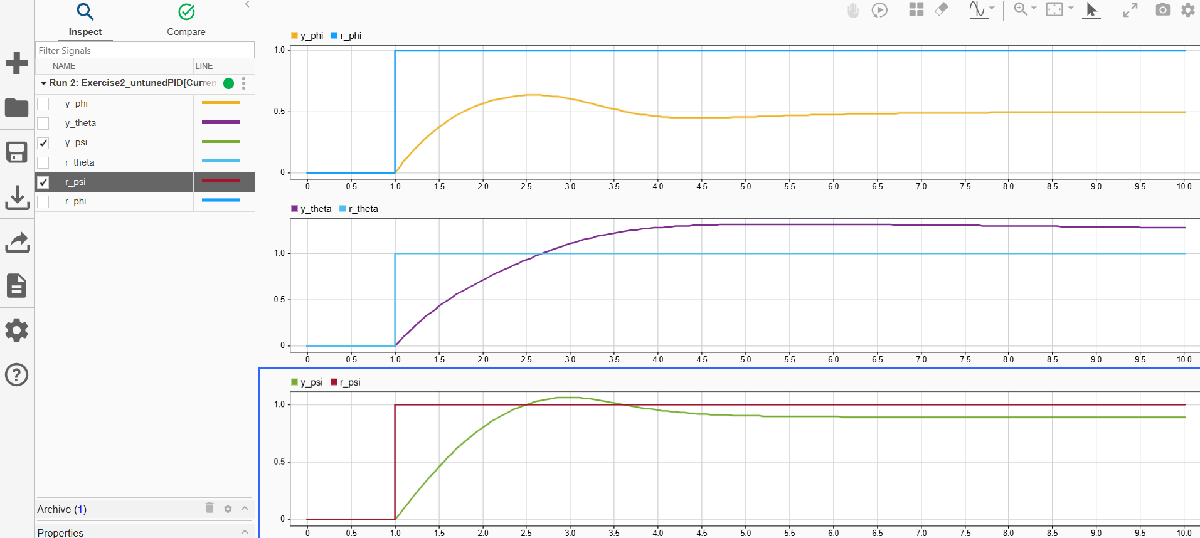

#### 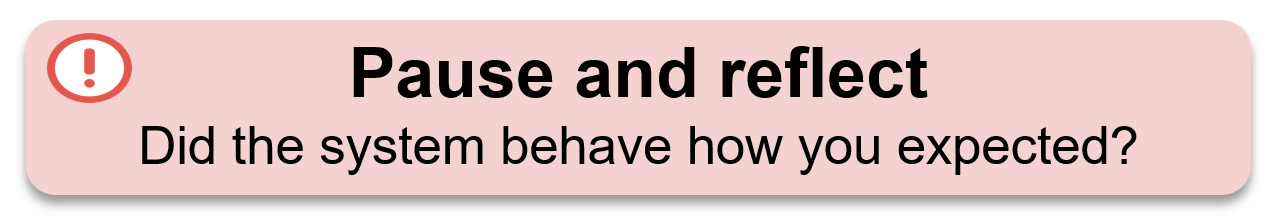

### 6) Tune the controllers by hand and compare

The difficulty in designing linear controllers to track principal axes reference commands is the plant derivatives are non-linear with respect to the angular velocities of the body. Linearizing around a single operating point simplified the problem too much! We can see why by walking through the tuning process by hand.

Linearize the rotational dynamics equations.

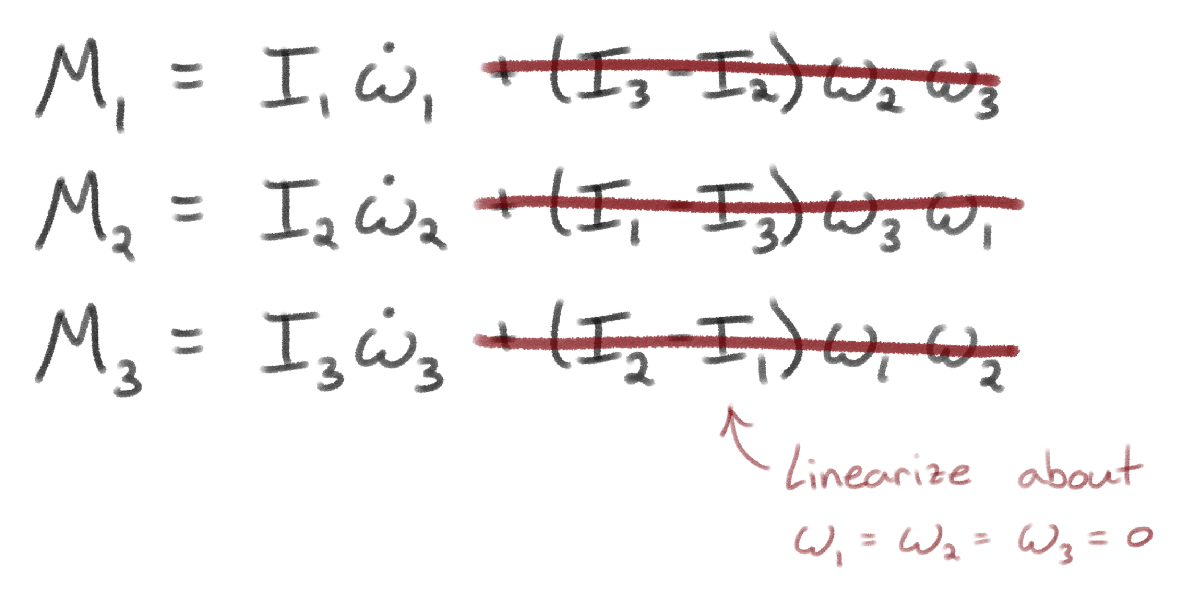

Since all three equations are essentially the same, we can see what's happening in each axis by looking at the first equation only. Both the input, M, and the angular velocity, $\dot{\omega}$, are functions of time.

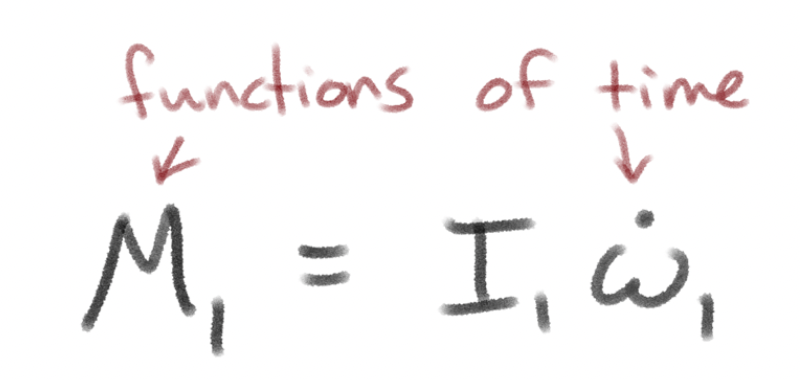

We can take the Laplace transform to convert the equation to the S-domain.

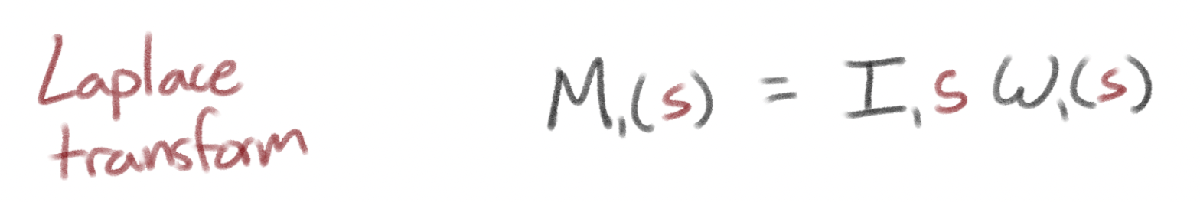

And rearrange to get the transfer function. This shows that there is a first order relationship between the input moments and the output angular velocity.

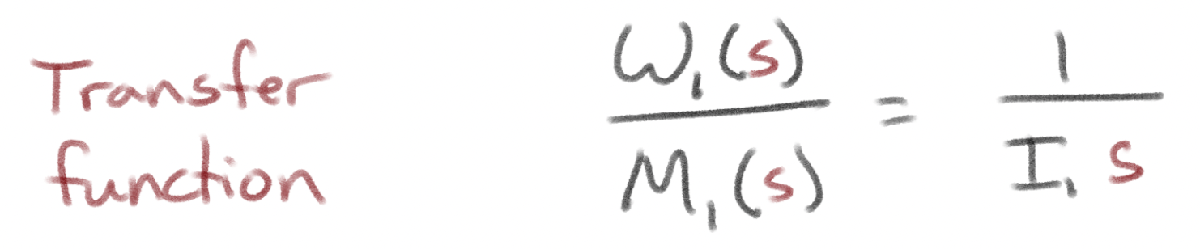

The closed loop block diagram of the system is as follows. The reference signal, r, is a desired attitude which is compared to the actual spacecraft attitude in one axis, $\theta$, to produce an error, e. The error is fed into a PD controller which produces the commanded moments, M. Using the above transfer function, we get the angular velocity, $\omega$, which we integrate to get angle, $\theta$.

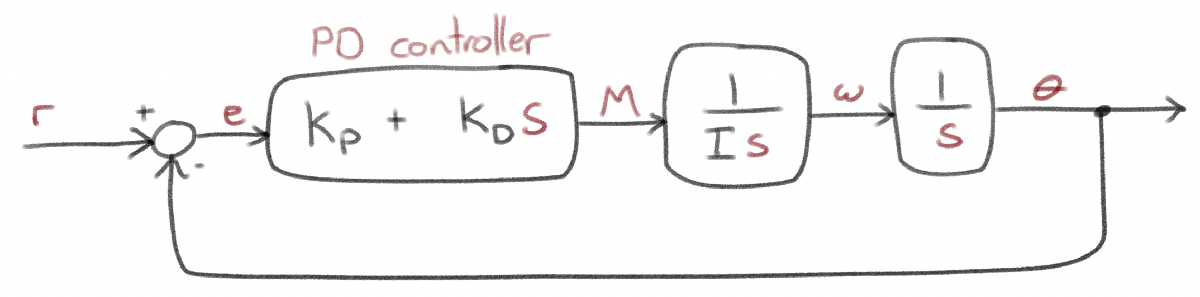

We can simplify this block diagram into the following transfer function which we can use to control the response to input R by choosing the controller gains Kp and Kd.

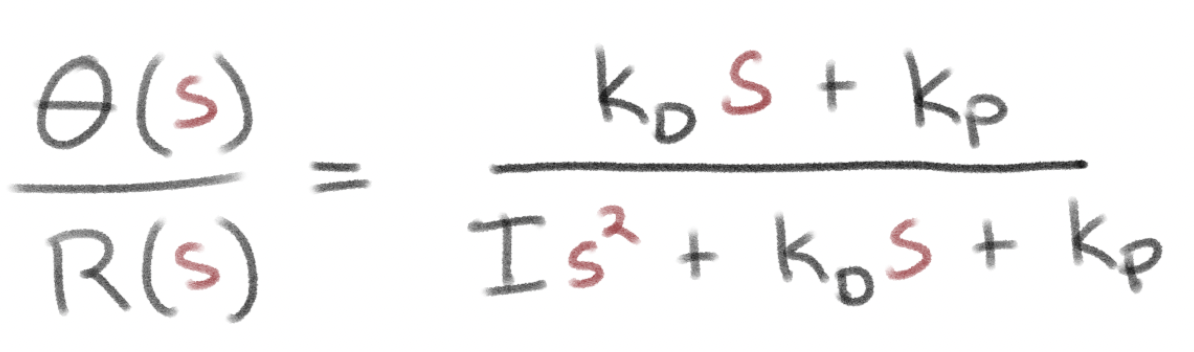

We can pick any Kp and Kd, but we want to meet certain performance goals. Specifically, we chose a tracking goal with response time of 2 seconds, peak error at 100%, and DC error at 0.1%. We can find out what this tracking goal means at [this help page](https://www.mathworks.com/help/control/ref/tuninggoal.tracking.html). The following image explains what this tracking goal looks like graphically.

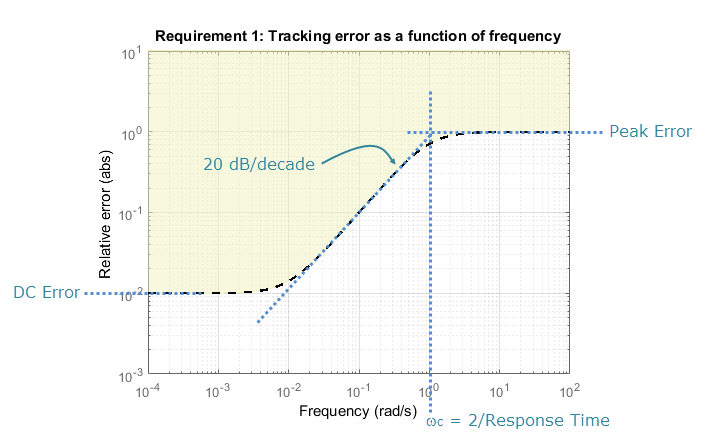

With a response time of 2 seconds, our target crossover frequency is 1 rad/s.

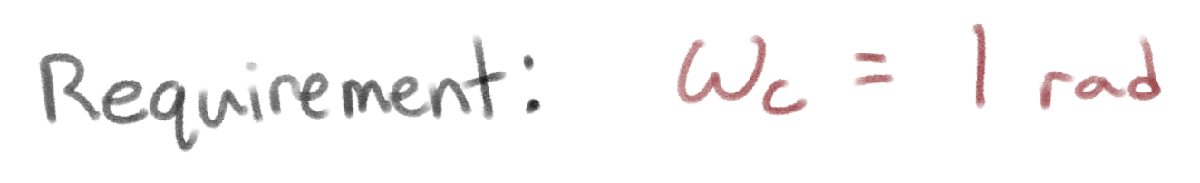

This corresponds to the following 1st order transfer function.

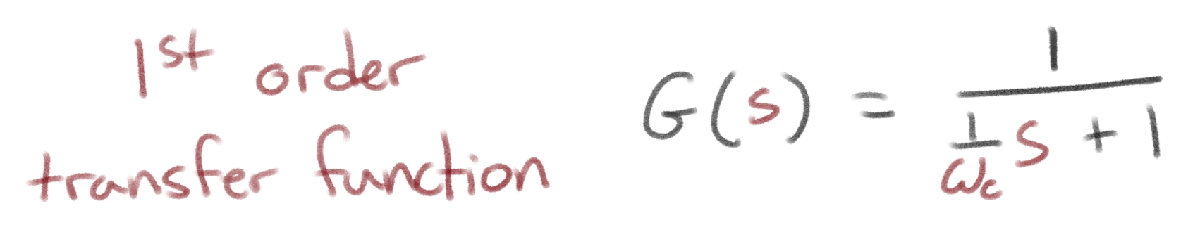

Therefore, the simplest solution is to find a Kp and Kd that makes our second order system behave like this first order system, where Wc = 1.

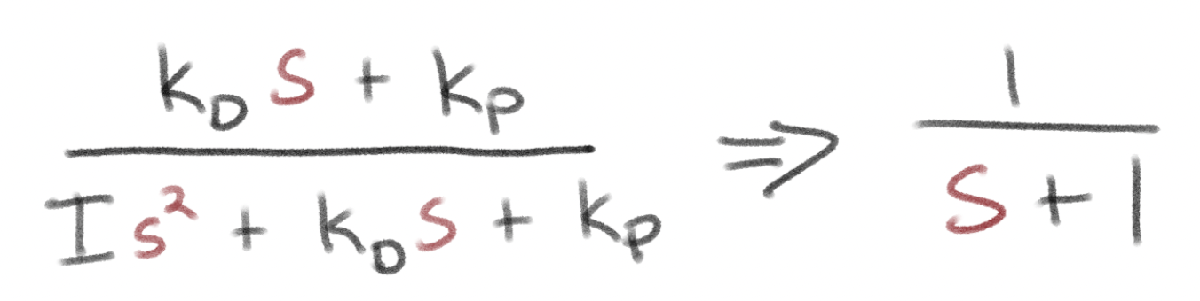

We can start by setting Kp = 0 and then simplifying the equation to remove the s in numerator and denominator. 

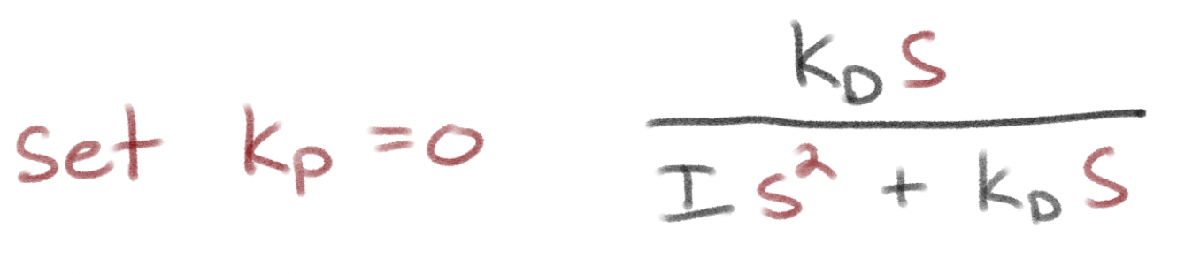

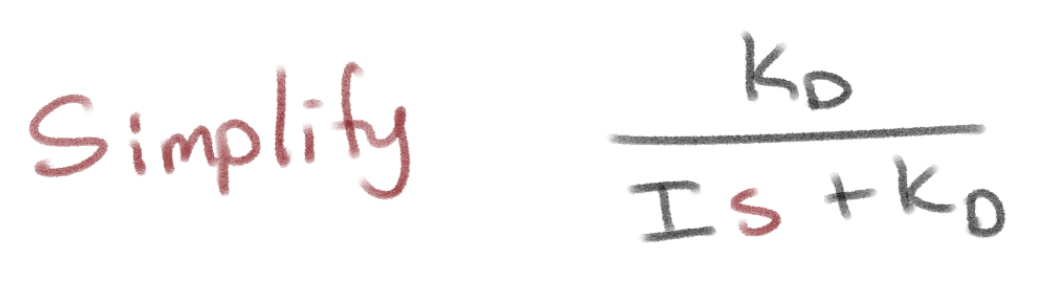

Then divide by Kd/Kd to get it in the same form as the requirement.

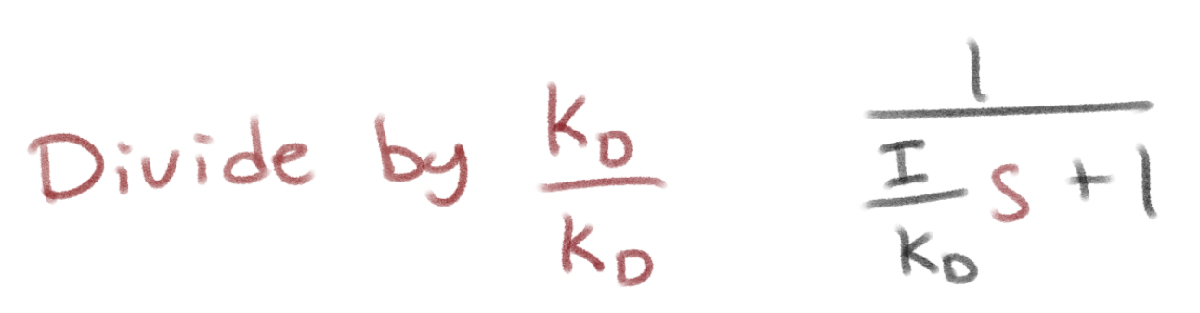

From here we can see that Kd must equal I. 

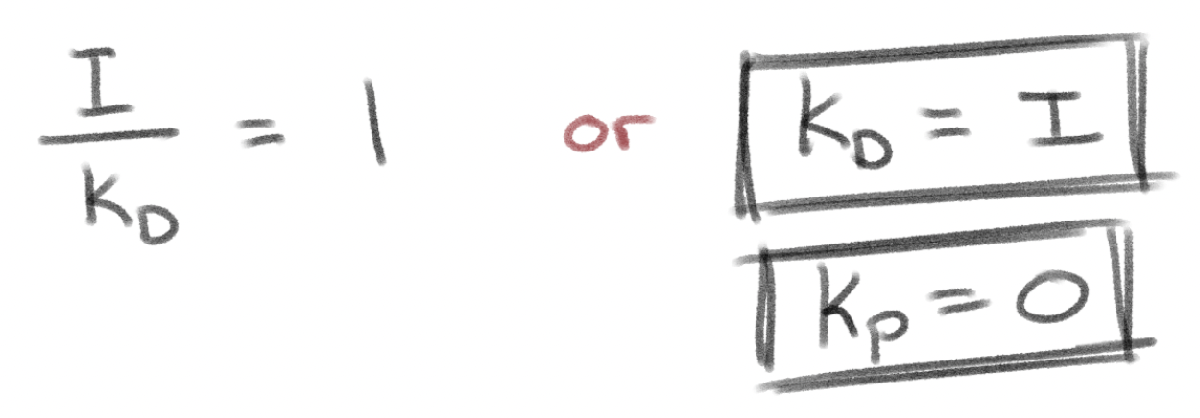

Therefore, the optimal controller that meets the stated requirements for the linearized dynamics is a derivative-only controller with gain equal to the moment of inertia in that principle axis. 

   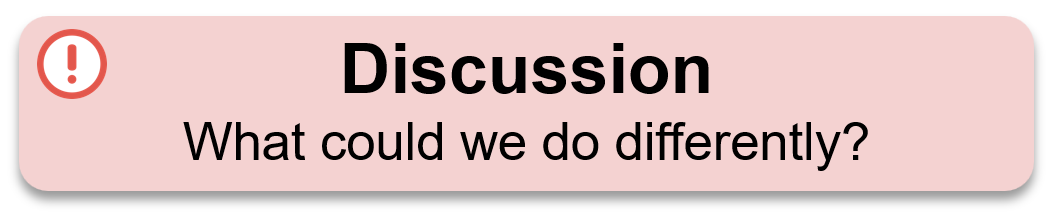

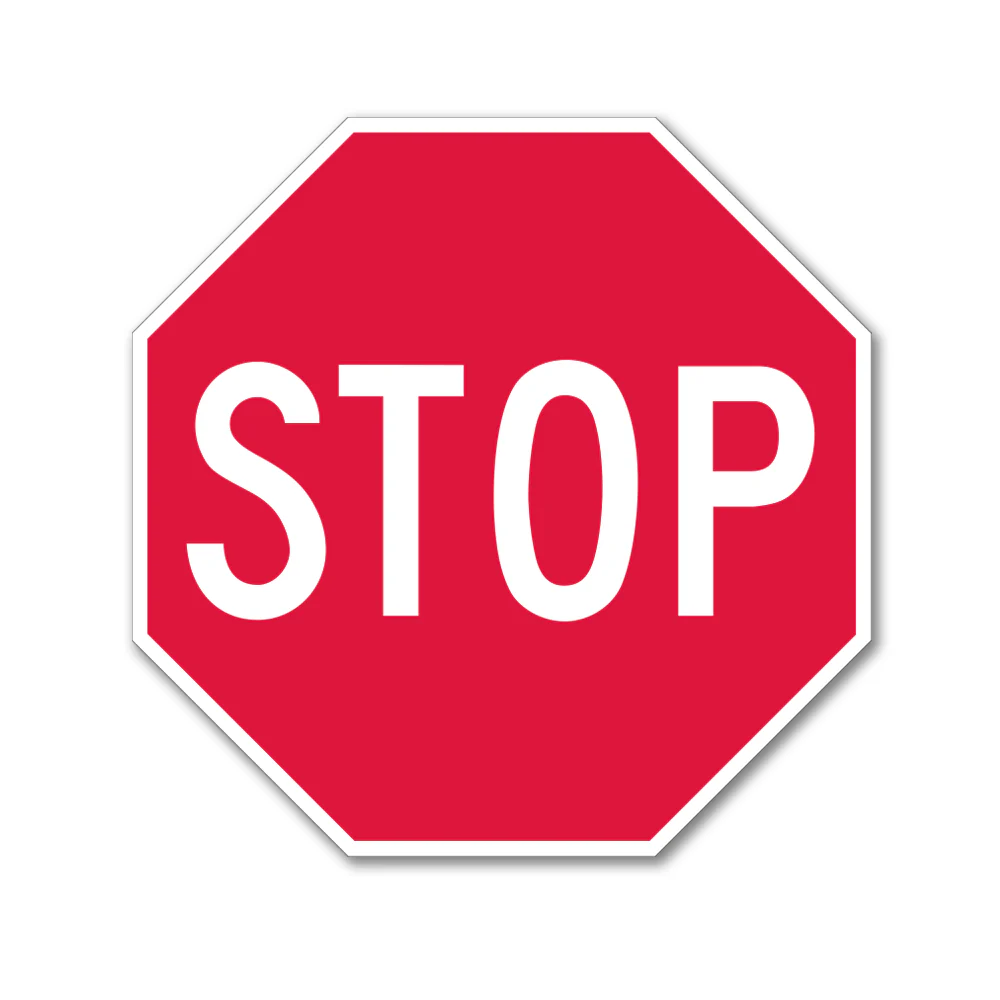

## Part 2: Tune PD Control + Decoupler + Dynamic Feedback Linearization

In this part you will

- Open the model with PD + Decoupler + Dynamic Feedback Linearization controllers

- Set up the tuning rules and conditions and tune the controllers

- Observe the results

- Close windows

### 1) Open the model with PD + Decoupler + Dynamic Feedback Linearization controllers

**Close any open Control System Tuner App windows**, choosing to not save the session.

Then, **run this section **to open the model.

% Close any previously open models
close_system("Exercise2_untunedPID",0);
close_system("Exercise2_tunedPID",0);

% Open model
open_system Exercise2_untuneddynfbklin

### 2) Set up the tuning rules and conditions and tune the controllers

Next, let's try linearizing the model about a single operating point about the nominal condition, then treating the nonlinearities as disturbances. 

**Re-open the Control System Tuner App** from the Simulink "apps" tab.

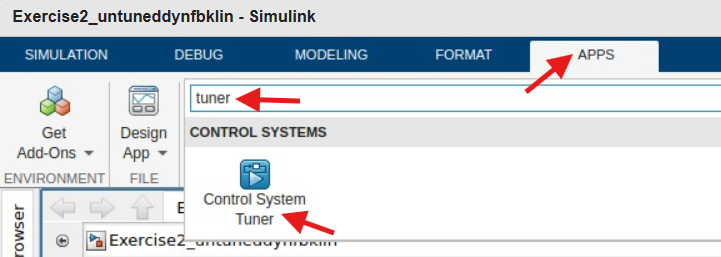

**Do it yourself!**  Follow the tuning steps in the [Exercise 2 Supplemental](matlab: open Exercise2Supplement) live script.

or

**Open a session that is ready to go! **Open Exercise2_UntunedDecouplerSession.mat

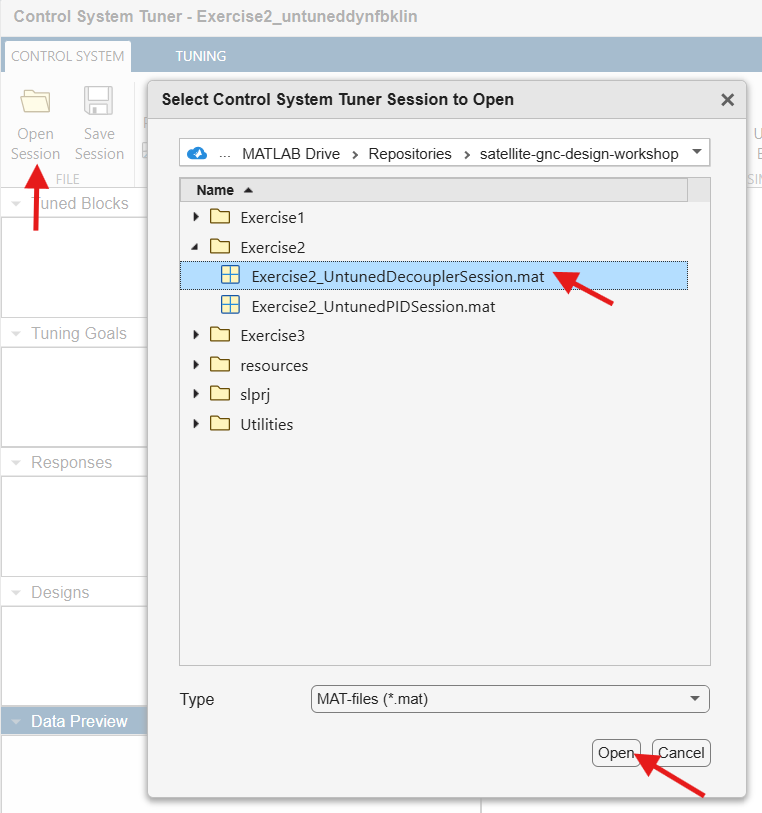

Notice how our current untuned decoupler gains don't meet our loop shape goals. The stability margins are in the yellow-colored region of the plots. **On the Tuning tab, click "Tune"** to have Control System Tuner find gain values that meet our criteria.

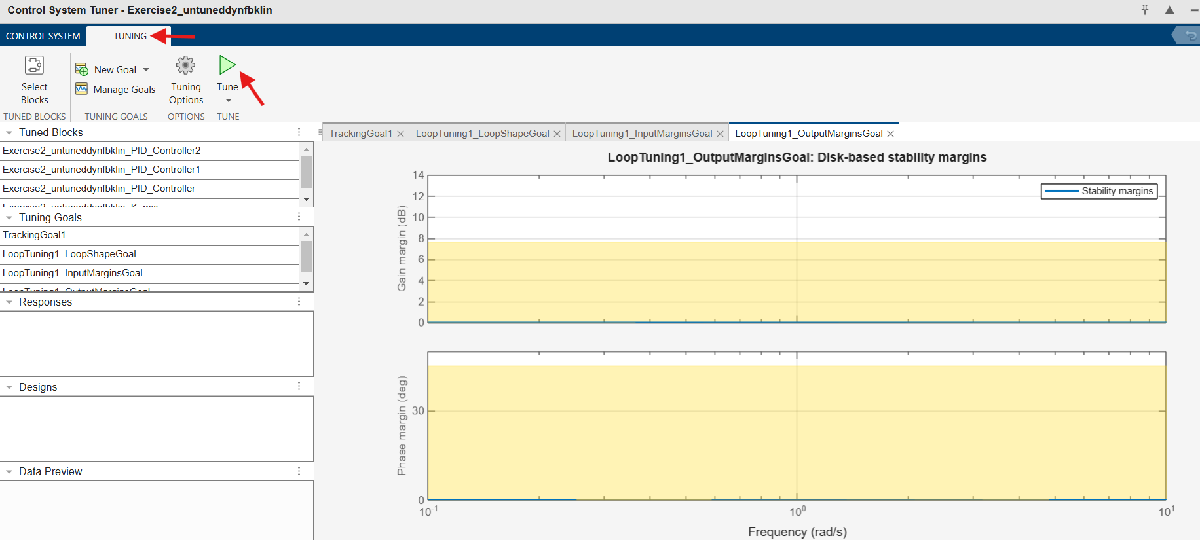

After tuning, the stability margins should not be in the yellow-colored region of the plot. Once you've verified this, you can update the PID blocks with the new gain values by **navigating to the Control System tab and clicking "Update Blocks"**. 

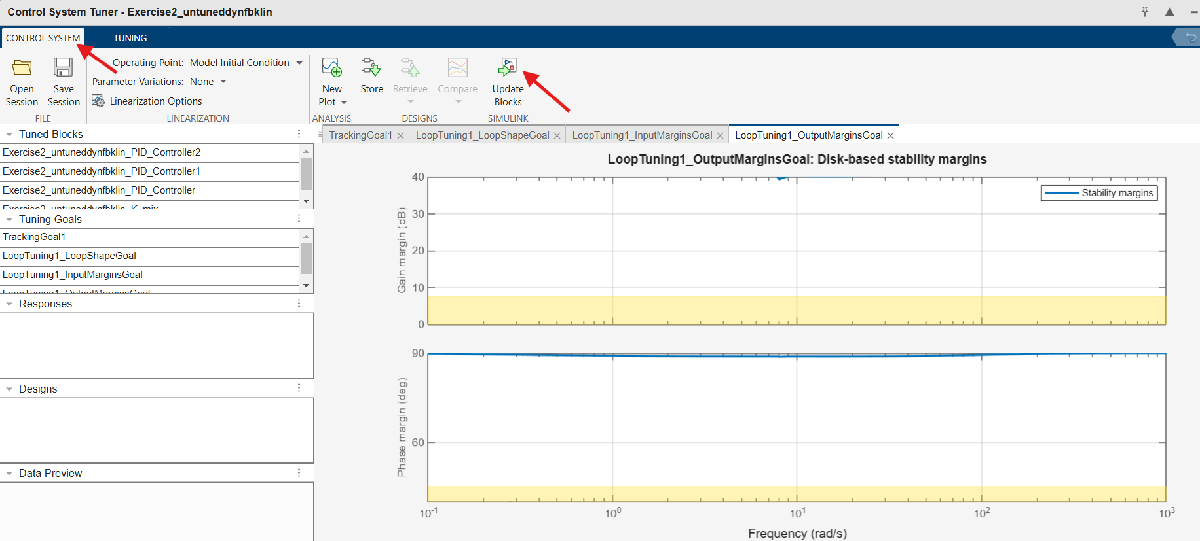

#### 

Catch up by [opening the solution model](matlab:open_system Exercise2_tuneddynfbklin) to evaluate the performance with these tuned gain values.

### 3) Observe the results

In the Simulink window, **run the tuned model.**

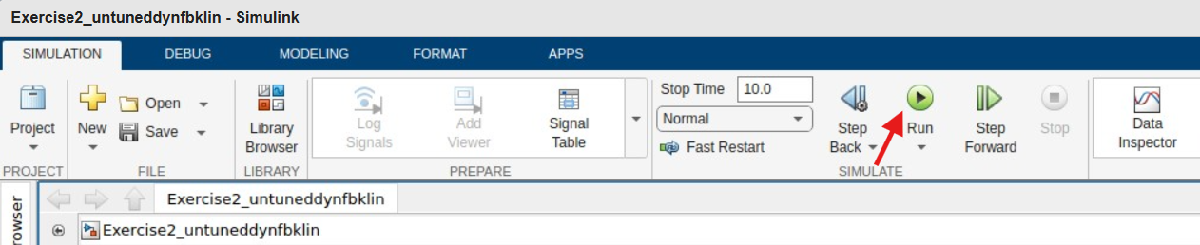

**Open the Data Inspector **to view controller performance from the simulation run.

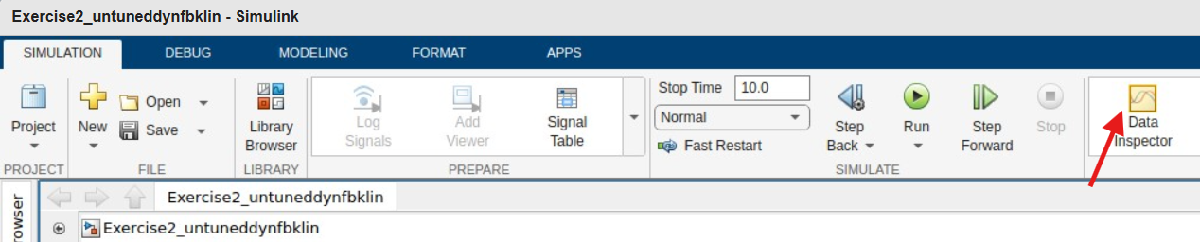

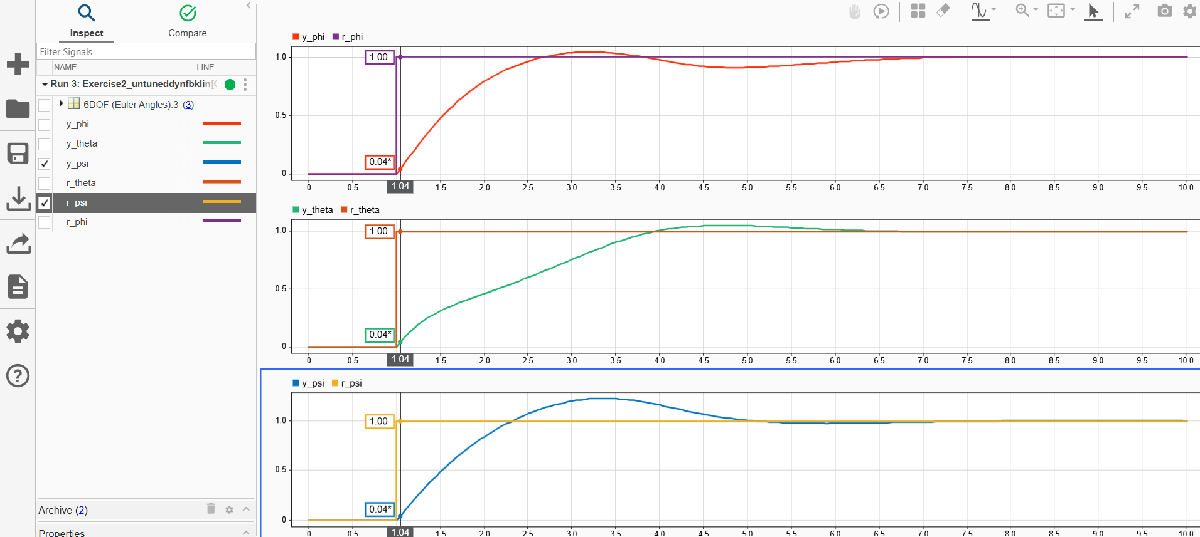

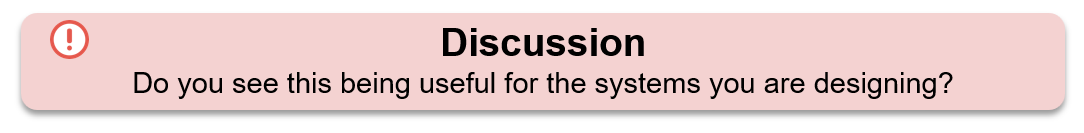

### 4) Close windows

**Close any open Control System Tuner App windows**, choosing to not save the session.

**Run this section** to close this exercise's models and open the live script for the next exercise.

close_system("Exercise2_untuneddynfbklin",0)
close_system("Exercise2_tuneddynfbklin",0)
open Exercise3.mlx